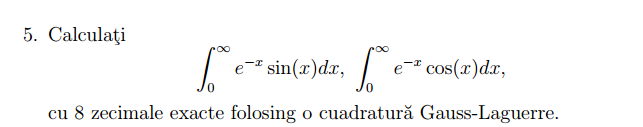

f1 = @(x) sin(x);  % f(x) = sin(x)
f2 = @(x) cos(x);  % f(x) = cos(x)

% Reference values (exact integrals known)
I1_exact = 0.5;
I2_exact = 0.5;
eps = 1e-8;

found1 = false;
found2 = false;
n = 1;
max_n = 100;

while ~(found1 && found2) && n <= max_n
    [nodes, weights] = gauss_laguerre(n, 0);  % mu = 0
    I1 = sum(weights .* f1(nodes));
    I2 = sum(weights .* f2(nodes));
    
    err1 = abs(I1 - I1_exact);
    err2 = abs(I2 - I2_exact);
    
    if ~found1 && err1 < eps
        n1 = n;
        found1 = true;
        fprintf('I1 accurate with n = %d, error = %.2e\n', n1, err1);
    end
    
    if ~found2 && err2 < eps
        n2 = n;
        found2 = true;
        fprintf('I2 accurate with n = %d, error = %.2e\n', n2, err2);
    end
    
    n = n + 1;
end

I1 accurate with n = 13, error = 1.14e-10


I2 accurate with n = 13, error = 5.00e-09



fprintf('\nMinimum nodes required:\n');


Minimum nodes required:


fprintf('I1 --> n = %d\n', n1);

I1 --> n = 13


fprintf('I2 --> n = %d\n', n2);

I2 --> n = 13
